# Visualization of Scientific Data 

All graphical output in MATLAB appear directly in a new separetly Command Window, which is known as **figure**. Each figure can contains menus inside, toolbars, and different options that allow changing some characteristics of the plot.

For creating a new, use the function *figure*:

figure

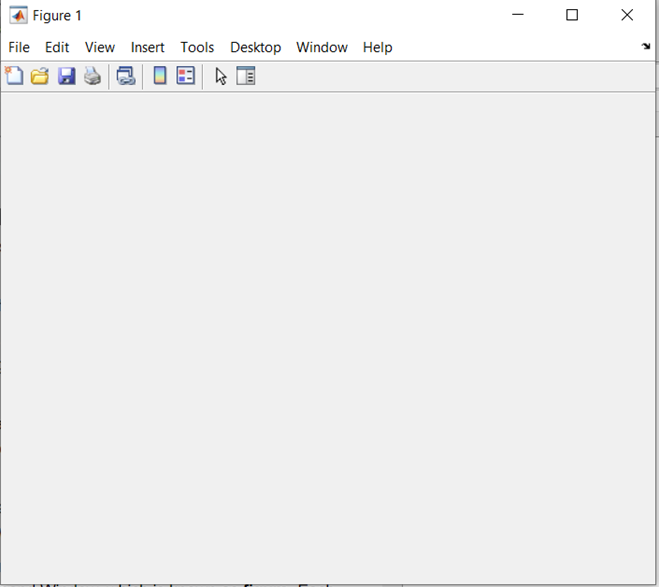

As you can see in the picture above, each graphical window has some properties that can change the characteristics of the plot such as: color, size, position, legend, etc. 

There are some figure properties that can be defined in advanced when creating the figure:

figure('Name','Test Window',"Position",[100 500 350 350],'MenuBar','none')

## 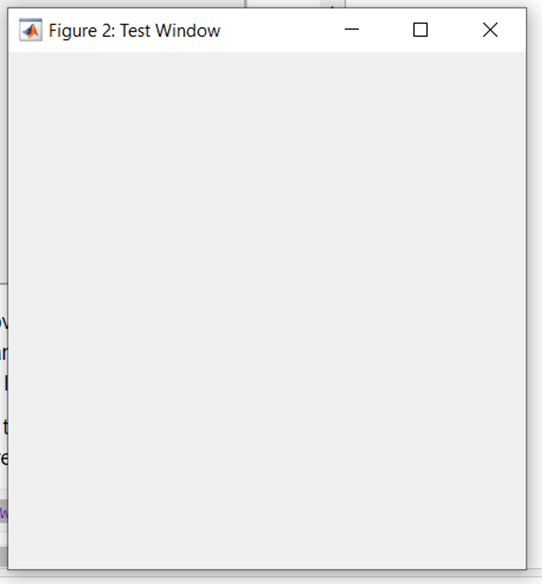

*clf* is a command for removing the figure (clear figure) and reseat all the properties:

clf reset

## Basic Plotting

Use plots to visualize data. For example, you can compare sets of data, track changes in data over time, or show data distribution. Create plots programmatically using graphics functions or interactively using the Plots tab at the top of the MATLAB desktop.

### Line Plots

Plot the cosine of x in the range [0, 3\pi]:

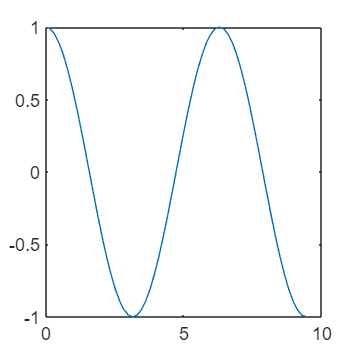

x = 0:pi/20:3*pi;
y = cos(x);
plot(x,y)

Change the linestyle, color or marker type: the color, line style and marker type can be specified using a single string:

figure;
plot(x,y, 'k--p')

Label the axis and the title, and also, specify the size of the font:

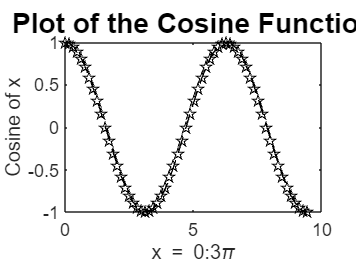

xlabel('x = 0:3\pi')
ylabel('Cosine of x')
title('Plot of the Cosine Function','FontSize',14)

Add a second plot on top of this one using the command *** hold on***:

hold on
y2 = tan(x+20);
plot(x,y2, 'r')

 Add a legend

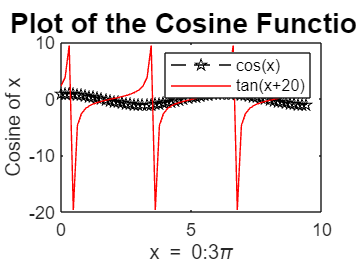

legend('cos(x)','tan(x+20)')

Adjust axes limits

xlim([0 3*pi])

Add a grid to the plot with teh command ***grid on***:

grid on

Insert text into a plot:

text(5, 2, 'Some text in the figure')

Plot two lines in just one plot:

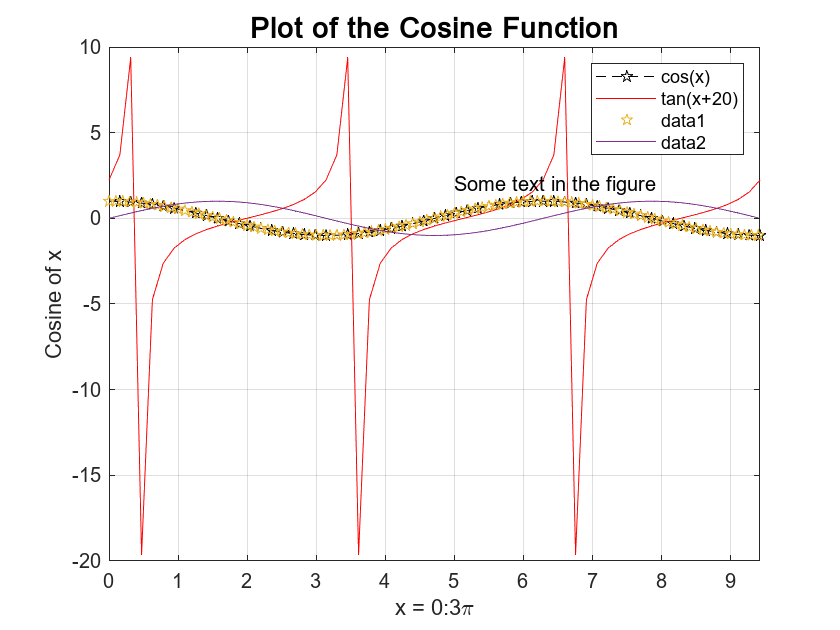

x = 0 : 0.1 : 3*pi;
y1 = cos(x);
y2 = sin(x);
plot(x, y1, 'p', x, y2, '-')

### Errorbar

Create a line plot with error bars at each data point.

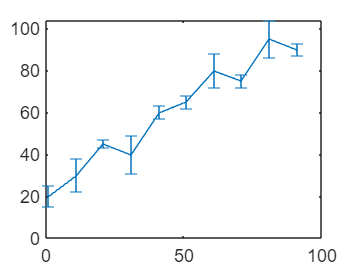

x = 1:10:100;
y = [20 30 45 40 60 65 80 75 95 90]; 
err = [5 8 2 9 3 3 8 3 9 3];
figure;
errorbar(x,y,err)

### Subplots

Plot two graphics into the same figure using a 2-by-1 subplot:

x = 0:pi/10:3*pi;
y = cos(x);
y2 = cos(x+10);

subplot(2,1,1) % Splits the figure into two rows and one column
plot(x,y, '--')
title('Cosine of x')

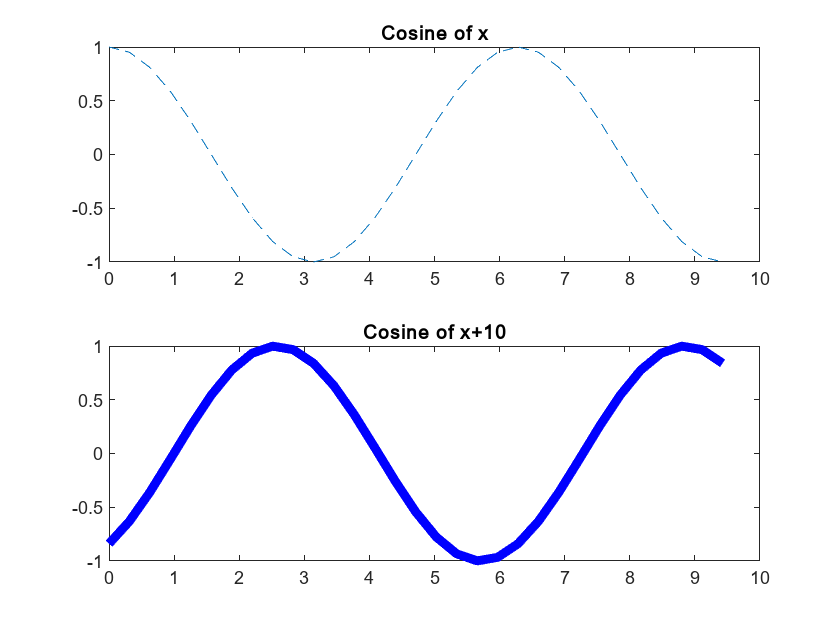

subplot(2,1,2)
plot(x,y2, 'b', 'linewidth', 4.5)
title('Cosine of x+10')

Plotting signals of different range:

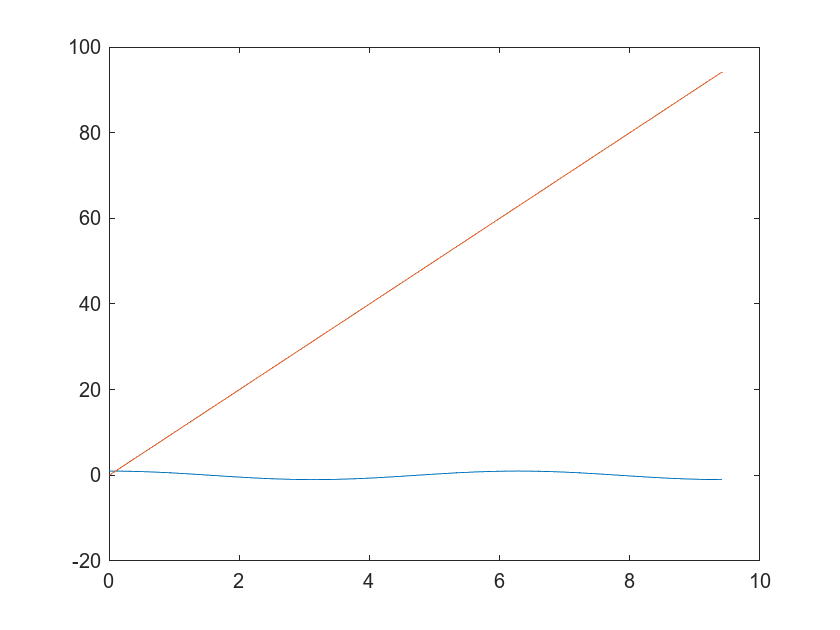

y2 = 10*x;
figure;
plot(x,y, x, y2)

Use 'yyaxis' to create a 2nd vertical axis:

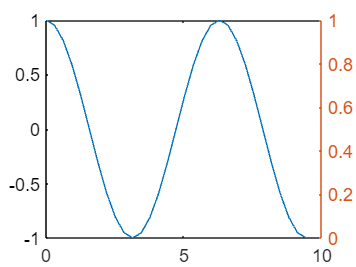

figure;
p1 = plot(x,y);
ylabel(gca, 'cos(x)', 'fontsize', 14, 'fontweight', 'bold')
yyaxis('left');
p2 = plot(x,y2);

ylabel(gca, 'y=10*x', 'fontsize', 14, 'fontweight', 'bold')
xlabel('x = 0:3\pi', 'fontsize', 12, 'fontweight', 'bold')

Saving the figures:

- as png

saveas(gcf, 'myPlot.png')

- as matlab figure, so we could edit it later using ***open('myPlot.fig')***

savefig('myPlot.fig')

Close all figures:

close all

Open a previously saved figure:

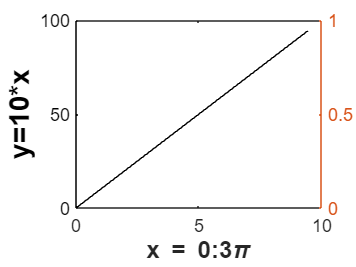

open('myPlot.fig')

### Histogram Plots

Histograms are a type of bar plot for numeric data that group the data into bins. 

y = randn(1, 2000);
figure;
histogram(y);

Compute some descriptive statistics (min, max, mean, median, std, var) and visualize these values over the histogram:

mean(y) % Mean value

ans = 0.0021

min(y) % Minimum value

ans = -3.2320

max(y) % Maximum value

ans = 3.5784

std(y) % Standard deviation

ans = 0.9991

var(y) % Variance

ans = 0.9983

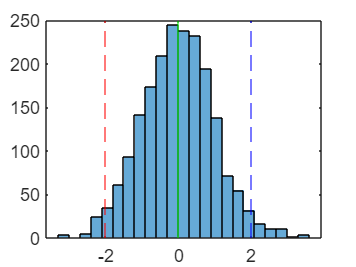

hold on
xline(mean(y), 'g-')
xline(-2*std(y), 'r--')
xline(2*std(y), 'b--')

### Scatter Plots

***scatter(x,y) ***creates a scatter plot with circles at the locations specified by the vectors x and y.

Create vectors x and y as cosine values with random noise:

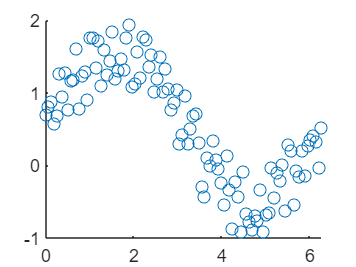

x = linspace(0,2*pi,100);
y = sin(x) + rand(1,100); 
figure;
scatter(x,y)

The size, color and type of the markers can be modified through optional arguments of the function

% scatter(x,y,size,color,marker)

For example, we can increase the size of the circles by a third variable:

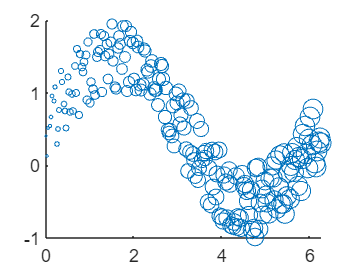

x = linspace(0,2*pi,200);
y = sin(x) + rand(1,200); 
sz = linspace(1,100,200);
figure;
scatter(x,y,sz)

Change the color according to a third variable:

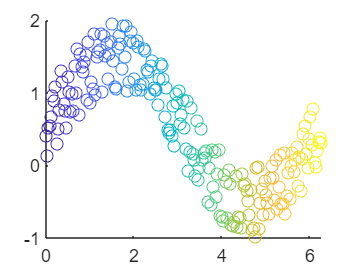

figure
scatter(x,y,[],sz)

Change the marker type to diamond:

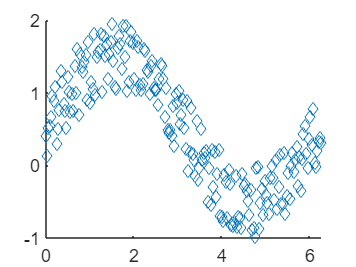

figure
scatter(x,y, 20, 'd') % fixed size to 20

## Graphic Models

With MATLAB is possible to create device independent graphics layer. 

The basic graphics are: 

**Core graphics objects:** include basic drawing like lines, points, test, axes, images (2D) and surfaces (3D) among so many others.

**Composite graphics objects:** they are core graphics that have been grouped together in order to create a more convenient interface.

In order to visualize the datam it is mandatory to create a graphics window containing a figure, axes, and a a view.

The **axes** define the frame where the figure will be displayed. The axes can be defined with the function *axes* but it is easier to configure them wit the function *view*.

The ***view*** is the particular orientation you set to display the visualization. The term *viewing* refers to the process of displaying a graphical scene from various directions by adjusting the camera position, changing the perspective, etc.

MATLAB viewing is composed of two basic areas:

- Positioning the viewpoint to orient the scene

- Setting the aspect ratio and relative axis scaling to control the shape of the objects being displayed

**Positioning the viewpoint:** The *view *function specifies the viewpoint by defining azimuth and elevation with respect to the axis origin. Azimuth is a polar angle in the *x-y* plane, with positive angles indicating counterclockwise rotation of the viewpoint. Elevation is the angle above (positive angle) or below (negative angle) the *x-y* plane.

MATLAB automatically selects a viewpoint that is determined by whether the plot is 2-D or 3-D:

- For 2-D plots, the default is azimuth = 0° and elevation = 90°.

- For 3-D plots, the default is azimuth = -37.5° and elevation = 30°.

`view``(2)` sets the default two-dimensional view, with az = 0, el = 90.

`view``(3)` sets the default three-dimensional view, with az = –37.5, el = 30.

`view``(az,el)` or `view``([az,el])` set the viewing angle for a three-dimensional plot.

The azimuth, az, is the horizontal rotation about the *z*-axis as measured in degrees from the negative *y*-axis. Positive values indicate counterclockwise rotation of the viewpoint. el is the vertical elevation of the viewpoint in degrees. Positive values of elevation correspond to moving above the object; negative values correspond to moving below the object.

The ***peaks*** function is a function of two variables, obtained by translating and scaling Gaussian distributions.

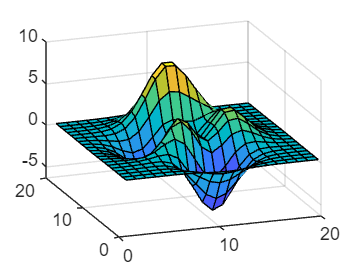

Z = peaks(20); 
figure; 
h = surf(Z); 
view([-20,25])

**Setting the aspect ratio and axis scale: **The *axis *command enables you to adjust the aspect ratio of graphs. The axis command also enables you to adjust the scaling of graphs. Normally MATLAB stretches the axes to fill the window and chooses appropriate axes ranges based on the maxima and minima of the plotted data. If you will be interactively rotating the visualization in the figure window you should use the *vis3d* option.

`axis``([``xmin xmax ymin ymax zmin zmax``])` sets the limits for the *x*-axis, *y*-axis and *z*-axis of the current axes.

axis vis3d freezes aspect ratio properties to enable rotation of 3-D objects and overrides stretch-to-fill.

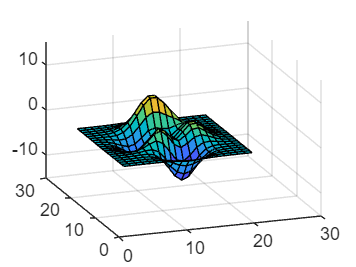

Z = peaks(20);
figure;
h = surf(Z);
view([-20,25]);
axis([0 30 0 30 -15 15]);

In the figures, **labels** can be added. The labels correspond to the name of each axes. The ***tittle*** command adds a tittle to teh figure, and also, you can add ***text*** anywhere in the figure.

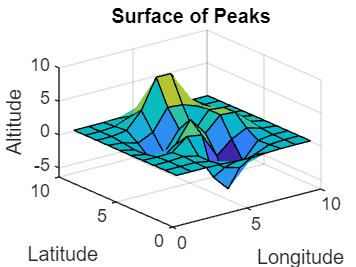

Z = peaks(10);
figure;
h = surf(Z);
view(3);
axis on;
xlabel('Longitude');
ylabel('Latitude');
zlabel('Altitude');
title('Surface of Peaks');

### Camera Toolbar

Inside the figure window, select de View Menu, Camera Toolbar. A new toolbar opens down the basic toolbar. 

This toolbar allows allow options: camera motion, selection or axis, lightinig the scene...

All this controls can be changed also with different commands:

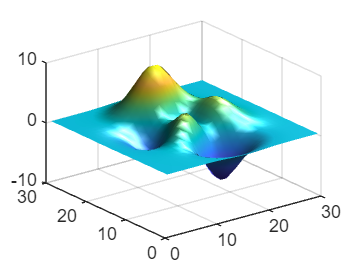

Z = peaks(30);
figure;
h = surf(Z);
view(3);
axis on;
light;
lighting phong;
camlight('right');
shading interp;

## Modeling Visualization Algorithms

Modeling algorithms offer details of a dataset in order to discover interesnting region in it.

### Matrix

The matrixes are represented as surfaces in 3D. The surface is created by joining adjacent points with lines. 

In MATLAB there are two different types of surface plots: mesh plots and surface plots. Mesh plots are colored wire-frame surfaces. Surface plots are colored faceted surfaces.

The ***mesh*** and ***surf*** functions create 3-D surface plots of matrix data. For the matrix Z the elements Z(i,j) define the height of a surface over an underlying (i,j) grid.

***Surface propterties*** provide additional control over the visual appearance of the surface. You can specify line styles, face coloring, lighting characteristics, etc.

The*** meshgrid*** unction generates X and Y arrays for 3-D plots.

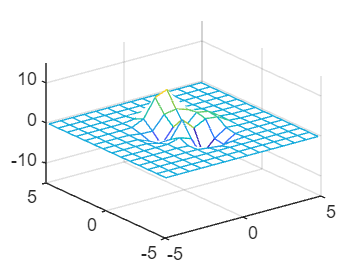

[X,Y] = meshgrid(-5:0.75:5);
Z = peaks(X,Y);
figure;
mesh(X,Y,Z);
view(3);
axis([-5 5 -5 5 -15 15]);
grid on;

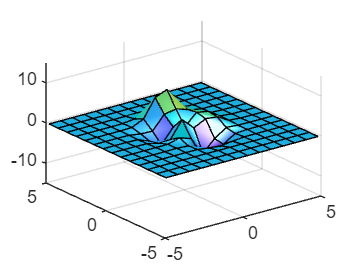

[X,Y] = meshgrid(-5:0.75:5);
Z = peaks(X,Y);
figure;
surf(X,Y,Z);
view(3);
axis([-5 5 -5 5 -15 15]);
grid on;
light;
lighting phong;
camlight('left');

### Slicing

Creates a cross-section of the dataset. Any kind of surface can be used to slice the volume, but the simplest technique is to use a plane to define the cutting surface thereby creating a planar cut. The color at each point is determined by 3-D interpolation into the volume. The cutting surface interpolates the data as it cuts in order to color the surface with values in the volume data where the slice is positioned. To create a planar cut we will use the ***slice*** function to do the actual cutting.

When you are moving along the plane, you can see the value of the cooridantes.

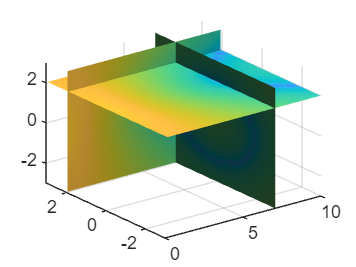

[x,y,z,v] = flow;
figure;
xslice = 7;
yslice = 2;
zslice = 2;
slice(x,y,z,v,xslice,yslice,zslice);
view(3);
axis on;
grid on;
light;
lighting phong;
camlight('right');
shading interp;

## 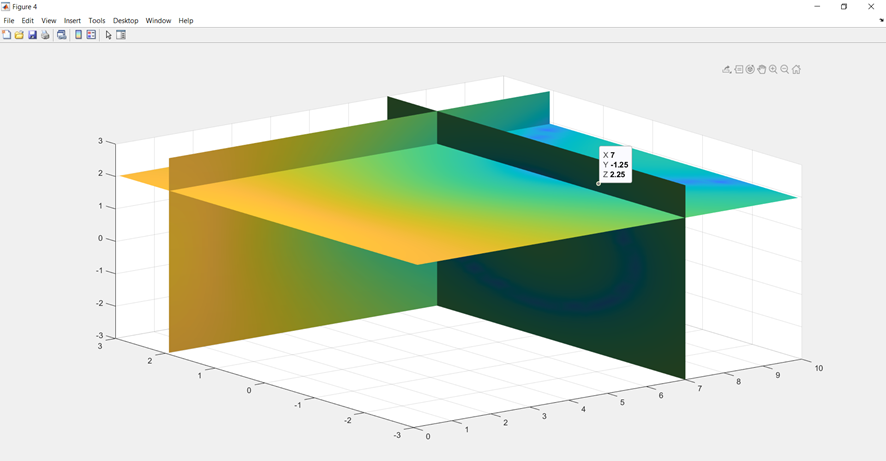

## Scalar Visualization

Scalars are single data values associated with each point in the dataset. There are several different algorithms to visualize scalar data. Two common algorithms are Color Mapping and Contouring.

### Color Mapping

Color mapping is a visualization technique in which each scalar value in the data set is mapped through a lookup table to a specific color. The scalar values are used as an index into the color lookup table. In MATLAB the color lookup table is called the ***colormap***. The colormap is a three-column 2-D matrix whose length is equal to the number of colors that are defined, and each row of the matrix defines a single color.

The primary MATLAB function used for color mapping is ***colormap***. Colormaps can be created with either MATLAB array operations or with one of the several color table generating functions (*jet*, *hsv*, *hot*, *cool*, *summer*, and *gray*).  The ***colorbar ***function displays the current color scalar mapping, either vertically or horizontally, in the figure window. 

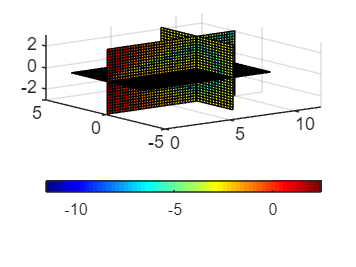

[x,y,z,v] = flow;
figure;
xslice = 7;
yslice = 0;
zslice = 0;
slice(x,y,z,v,xslice,yslice,zslice);
view(3);
axis([0 12 -5 5 -3 3]);
grid on;
colormap(jet(64));
colorbar('horizontal');

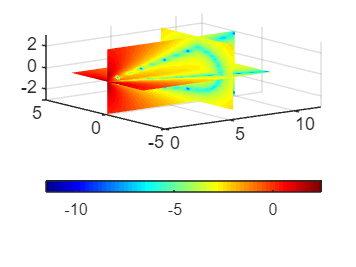

[x,y,z,v] = flow;
figure;
xslice = 7;
yslice = 0;
zslice = 0;
slice(x,y,z,v,xslice,yslice,zslice);
view(3);
axis([0 12 -5 5 -3 3]);
grid on;
colormap(jet(64));
colorbar('horizontal');
shading interp;

If instead of mapping the lower scalar values to blues and the higher values to reds, we wish to map the lower values to reds and higher values to blues we can use the ***flipud*** function. 

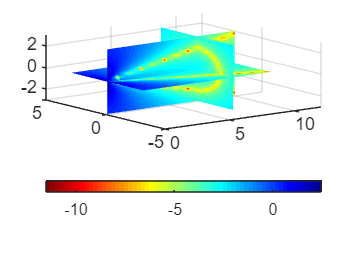

[x,y,z,v] = flow;
figure;
xslice = 7;
yslice = 0;
zslice = 0;
slice(x,y,z,v,xslice,yslice,zslice);
view(3);
axis([0 12 -5 5 -3 3]);
grid on;
colormap(flipud(jet(64)));
colorbar('horizontal');
shading interp;

And if instead of mapping the entire scalar range of the data into the color table, we wish to set a specific range (in terms of minimum and maximum) of the data that is mapped, we can adjust the color limits. Adjusting the color limits with the ***caxis ***function enables us to emphasize a particular range of interest in the data. 

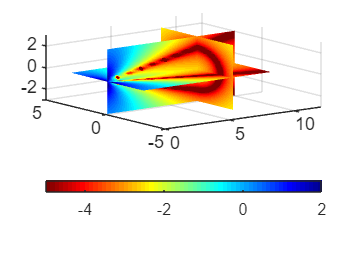

[x,y,z,v] = flow;
figure;
xslice = 7;
yslice = 0;
zslice = 0;
slice(x,y,z,v,xslice,yslice,zslice);
view(3);
axis([0 12 -5 5 -3 3]);
grid on;
colormap(flipud(jet(64)));
caxis([-5.0,2.0]);
colorbar('horizontal');
shading interp;

### Contours / Isosurfaces

Contouring is a technique where one constructs a boundary between distinct regions in the data. Contours are lines or surfaces of constant scalar value. This is a natural extension from color mapping as our eyes instinctively separate similarly colored areas into distinct regions. The first step in contouring is to explore the data space to find points near a contour or region of interest. Once found these points are then connected into either contour lines (isolines) for two-dimensional data or into surfaces (isosurfaces) for three-dimensional data. The lines or surfaces can also be color mapped using the scalar data. The primary MATLAB functions used for creating contour lines are ***contour, countour3 ***and ***contourslice***.  

`contour``(X,Y,Z,v)` draws a contour plot of matrix Z with contour lines at the data values specified in the vector *v*.

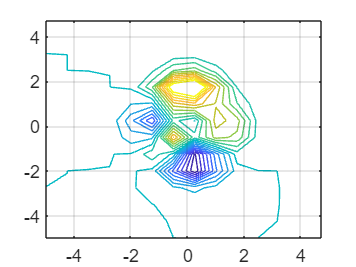

[X,Y] = meshgrid(-5:0.75:5);
Z = peaks(X,Y);
figure;
isovalues = (-5.0:0.5:5.0);
contour(X,Y,Z,isovalues);
view(2);
axis on;
grid on;

`contour3(X,Y,Z,v)` draws a contour plot of matrix Z in a 3-D view using X and Y to determine the x- and y-axis limits.

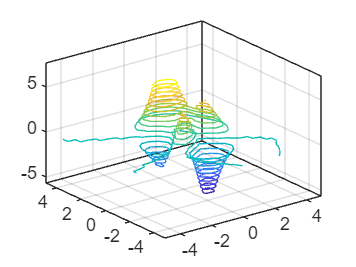

[X,Y] = meshgrid(-5:0.45:5);
Z = peaks(X,Y);
figure;
isovalues = (-5.0:0.5:5.0);
contour3(X,Y,Z,isovalues);
view(3);
axis on;
grid on;

`contourslice(X,Y,Z,V,Sx,Sy,Sz,v)` draws contour plots in the x-, y-, and z-axis aligned planes at the points in the vectors Sx, Sy, Sz.

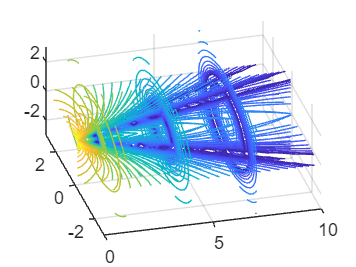

[x,y,z,v] = flow;
figure;
xslice = (1:3:12);
yslice = 0;
zslice = 0;
isovalues = (-5.0:0.25:5.0);
contourslice(x,y,z,v,xslice,yslice,zslice,isovalues);
view([-15 50]);
axis on;
grid on;